# Initialization

clear all;
data = load("sub-x32541_task-conflict.emg.mat");
struct = data.x32541_conflict000_wave_data;

x_units = struct.xunits;
start_t = struct.start;
delta_t = struct.interval;
sampling = 1 / delta_t;
points = struct.points;
frames = struct.frameinfo;
channels = struct.chaninfo;
values = struct.values;
t = linspace(start_t, delta_t*double(points), points);

clear ("data");

data = load("32541_1_2022_Jun_17_1139_V_cued_r_time.mat");
trial_list = data.triallist;
stimuli_onset = data.stimonset;
press_time = data.presstime;
press_name = data.pressname;
clear('data');

% BPF -> filtering data and rectifying
cutoff_low = 40; % motoneurons fire at 14 +- 4 hz, but I want to filter out movement remaints
cutoff_high = 400; % too fast for a motorneuron
filter_order = ceil( (sampling / (cutoff_high - cutoff_low)) * (20 / 22)); % Fred Harris rule

[b, a] = butter(filter_order, [cutoff_low/(sampling/2), cutoff_high/(sampling/2)], 'bandpass');

filtered_signal = filtfilt(b, a , values);

% Removing DC offset by removing the avg
filtered_signal = filtered_signal - mean(filtered_signal);

% Signal rectification
rectified_signal = abs(filtered_signal);

sd = std(rectified_signal);

% Enveloping signal
cutoff = 10; 
filter_order = ceil( (sampling / (cutoff_high - cutoff_low)) * (20 / 22));

[b, a] = butter(filter_order, cutoff/(sampling/2), 'low');
enveloped_signal = filtfilt(b, a , rectified_signal); % display purposes

% Power spectrum
ps = fft(values);
ps_f = fft(rectified_signal);
n = length(ps(:,1,1));
f = (0:n-1)*(sampling/n);
power = abs(ps).^2 / n;
power_f = abs(ps_f).^2 / n;

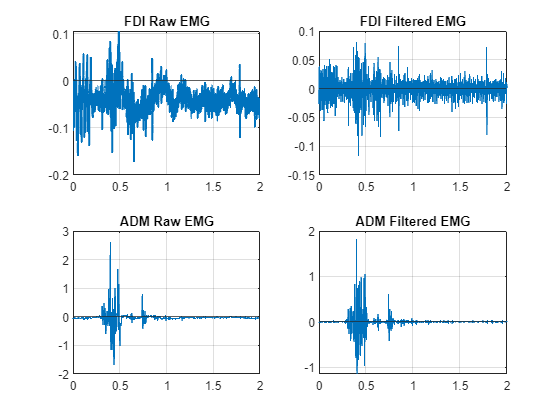

% Plotting
figure()

subplot(2,2,1)
xlabel(x_units)
ylabel(channels(1).units)
plot(t,values(:,1,2), 'LineWidth', 1.5)
yline(0)
title(channels(1).title + " Raw EMG")
grid("on")

subplot(2,2,3)
xlabel(x_units)
ylabel(channels(2).units)
plot(t,values(:,2,2))
yline(0)
title(channels(2).title + " Raw EMG")
grid("on")

subplot(2,2,2)
xlabel(x_units)
ylabel(channels(1).units)
plot(t,filtered_signal(:,1,2))
yline(0)
title(channels(1).title + " Filtered EMG")
grid("on")

subplot(2,2,4)
xlabel(x_units)
ylabel(channels(2).units)
plot(t,filtered_signal(:,2,2))
yline(0)
title(channels(2).title + " Filtered EMG")
grid("on")

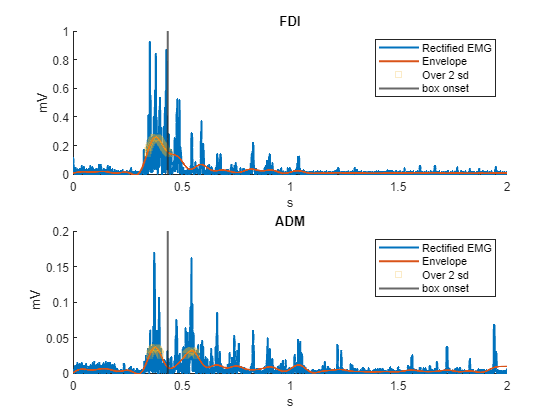

% type 1

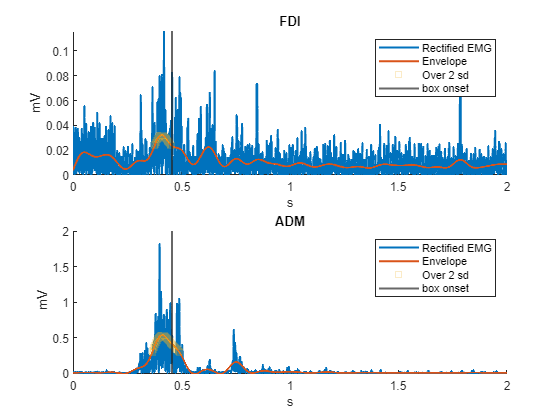

figure()

for i = 1:length(values(1,1:2,2)) % 6 channels: 3 to 6 are noise
    onsets_t = find(enveloped_signal(:,i,2) >  2 * sd(:,i,2));
    closest_t = interp1(t,t, press_time(2), 'nearest');
    closest_t = find(t == closest_t);

    subplot(length(rectified_signal(1,1:2,1)),1,i)
    hold on
    plot(t, rectified_signal(:,i,2), t, enveloped_signal(:,i,2), 'LineWidth', 1.5)
    scatter(t(onsets_t), enveloped_signal(onsets_t,i,2), 's')
    xline(t(closest_t),'LineWidth',1.5)
    hold off
    title(channels(i).title)
    xlabel(x_units)
    ylabel(channels(i).units)
    legend('Rectified EMG', 'Envelope', 'Over 2 sd', 'box onset')
end % vibration fdi heterotropic

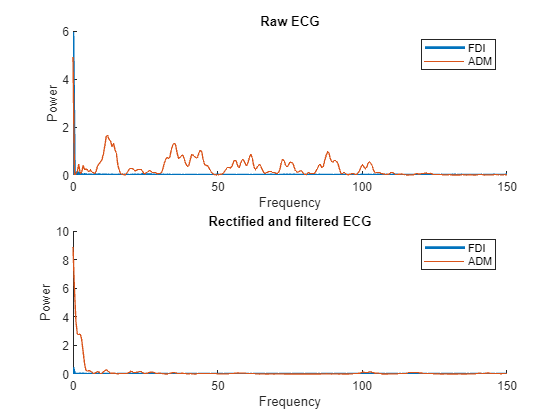


figure()
subplot(2,1,1)
hold on
plot(f,power(:,1,2),'LineWidth',2)
plot(f, power(:,2,2))
hold off
xlabel('Frequency')
ylabel('Power')
xlim([0,150])
legend('FDI','ADM')
title('Raw ECG')

subplot(2,1,2)
hold on
plot(f,power_f(:,1,2),'LineWidth',2)
plot(f, power_f(:,2,2))
hold off
xlabel('Frequency')
ylabel('Power')
xlim([0,150])
legend('FDI','ADM')
title('Rectified and filtered ECG')

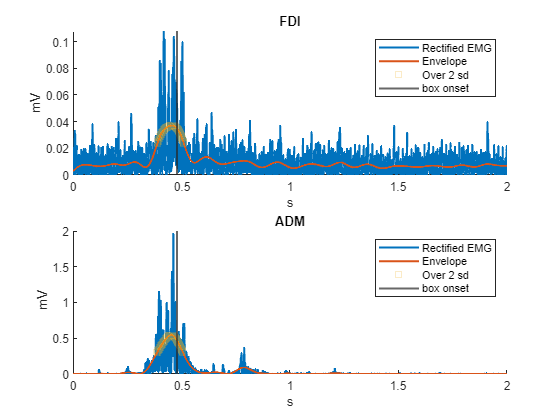

% type 3

figure()
for i = 1:length(values(1,1:2,3)) % 6 channels: 3 to 6 are noise
    onsets_t = find(enveloped_signal(:,i,3) >  2 * sd(:,i,3));
    closest_t = interp1(t,t, press_time(3), 'nearest');
    closest_t = find(t == closest_t);

    subplot(length(rectified_signal(1,1:2,3)),1,i);
    hold on
    plot(t, rectified_signal(:,i,3), t, enveloped_signal(:,i,3), 'LineWidth', 1.5)
    scatter(t(onsets_t), enveloped_signal(onsets_t,i,3), 's')
    xline(t(closest_t),'LineWidth',1.5)
    hold off
    title(channels(i).title)
    xlabel(x_units)
    ylabel(channels(i).units)
    legend('Rectified EMG', 'Envelope', 'Over 2 sd', 'box onset')
end

% type 4
figure()

for i = 1:length(values(1,1:2,7)) % 6 channels: 3 to 6 are noise
    onsets_t = find(enveloped_signal(:,i,7) >  2 * sd(:,i,7));
    closest_t = interp1(t,t, press_time(7), 'nearest');
    closest_t = find(t == closest_t);

    subplot(length(rectified_signal(1,1:2,1)),1,i)
    hold on
    plot(t, rectified_signal(:,i,7), t, enveloped_signal(:,i,7), 'LineWidth', 1.5)
    scatter(t(onsets_t), enveloped_signal(onsets_t,i,7), 's')
    xline(t(closest_t),'LineWidth',1.5)
    hold off
    title(channels(i).title)
    xlabel(x_units)
    ylabel(channels(i).units)
    legend('Rectified EMG', 'Envelope', 'Over 2 sd', 'box onset')
end

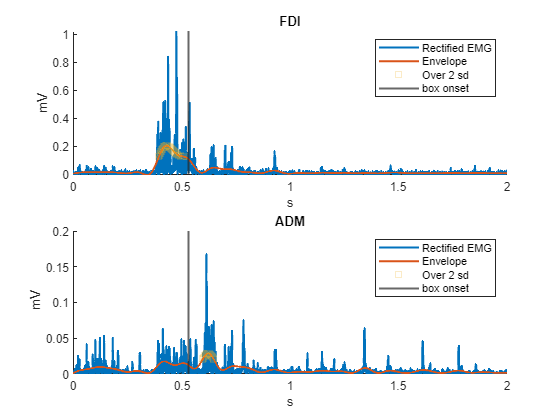

%type 2
figure()

for i = 1:length(values(1,1:2,14)) % 6 channels: 3 to 6 are noise
    onsets_t = find(enveloped_signal(:,i,14) >  2 * sd(:,i,14));
    closest_t = interp1(t,t, press_time(14), 'nearest');
    closest_t = find(t == closest_t);

    subplot(length(rectified_signal(1,1:2,1)),1,i)
    hold on
    plot(t, rectified_signal(:,i,14), t, enveloped_signal(:,i,14), 'LineWidth', 1.5)
    scatter(t(onsets_t), enveloped_signal(onsets_t,i,14), 's')
    xline(t(closest_t),'LineWidth',1.5)
    hold off
    title(channels(i).title)
    xlabel(x_units)
    ylabel(channels(i).units)
    legend('Rectified EMG', 'Envelope', 'Over 2 sd', 'box onset')
end

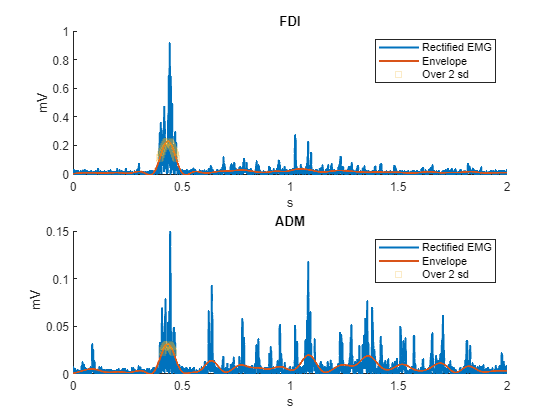

% 99 case
figure()

for i = 1:length(values(1,1:2,9)) % 6 channels: 3 to 6 are noise
    onsets_t = find(enveloped_signal(:,i,9) >  2 * sd(:,i,9));
    % closest_t = interp1(t,t, press_time(9), 'nearest');
    % closest_t = find(t == closest_t);

    subplot(length(rectified_signal(1,1:2,1)),1,i)
    hold on
    plot(t, rectified_signal(:,i,9), t, enveloped_signal(:,i,9), 'LineWidth', 1.5)
    scatter(t(onsets_t), enveloped_signal(onsets_t,i,9), 's')
    % xline(t(closest_t),'LineWidth',1.5)
    hold off
    title(channels(i).title)
    xlabel(x_units)
    ylabel(channels(i).units)
    legend('Rectified EMG', 'Envelope', 'Over 2 sd')
end

% TODO: batch statistic
% use ps to identify what's moving -> higher power at low frequency ->
% differentiation?
% TODO: emg for vibration, ps for finger. reaction time?